% Second order transfer function with varying zeta

## STEP -1 : Make a 2nd order Transfer Function

%Recall the generic form of the second order transfer function
% H(s) = wn^2/(s^2 + 2*zeta*wn*s + wn^2)
%For illsutration let us assume 
wn = 2; % Any value > 0 can be taken 
%-- Now based on zeta there are different cases.

## Step 1: Zeta > 1

zeta_a = 1.5;
NUM_a = wn*wn; DEN_a = [1 2*zeta_a*wn wn*wn];
H_a = tf(NUM_a,DEN_a);
P_a = pole(H_a);
Z_a = zero(H_a);
% Response to step input
Ha_step = step(H_a);

## Step 2: Zeta = 1

zeta_b = 1;
NUM_b = wn*wn; DEN_b = [1 2*zeta_b*wn wn*wn];
H_b = tf(NUM_b,DEN_b);
P_b = pole(H_b);
Z_b = zero(H_b);
% Response to step input
Hb_step = step(H_b);

## Step 3: Zeta < 1

zeta_c = 0.75;
NUM_c = wn*wn; DEN_c = [1 2*zeta_c*wn wn*wn];
H_c = tf(NUM_c,DEN_c);
P_c = pole(H_c);
Z_c = zero(H_c);
% Response to step input
Hc_step = step(H_c);

## Step 2- Plot and compare responses

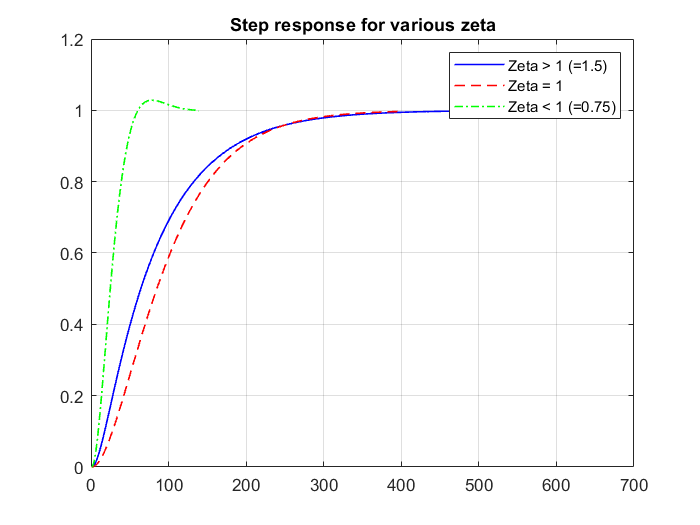

figure;plot(Ha_step,'-b','LineWidth',1); hold on;plot(Hb_step,'--r','LineWidth',1);
hold on; plot(Hc_step,'-.g','LineWidth',1);grid on;
legend('Zeta > 1 (=1.5)','Zeta = 1','Zeta < 1 (=0.75)')
title('Step response for various zeta');

%We have already seen that for zeta = 0, response is oscillating.